clc
clear
close all

% folderPath = '/Users/longxin/MATLAB-Drive/Q4/Radar_Project/Dataset/Image';
% folderPath = 'C:\Users\11362\Downloads\Dataset\image';
folderPath = 'D:\Users\11362\MATLAB Drive\Q4\Radar_Project\Dataset\image';
% folderPath = 'C:\Users\11362\OneDrive\all_radar\image';

filePath = fullfile(folderPath, 'all_labels.mat');
checkpointPath = 'D:\Users\11362\MATLAB Drive\Q4\Radar_Project\checkpoint';

Labels = load(filePath);
Labels = categorical(Labels.classLabels);

% Create an imageDatastore object from the cell array of images
% imds = imageDatastore(imagesCell);
imds = imageDatastore(folderPath);
imds.Labels = Labels;

disp(imds);

  ImageDatastore with properties:

                       Files: {
                              ' ...\Q4\Radar_Project\Dataset\image\001_mon_wal_1_1_segment1.png';
                              ' ...\Q4\Radar_Project\Dataset\image\001_mon_wal_1_1_segment2.png';
                              ' ...\Q4\Radar_Project\Dataset\image\001_mon_wal_1_1_segment3.png'
                               ... and 277 more
                              }
                     Folders: {
                              'D:\Users\11362\MATLAB Drive\Q4\Radar_Project\Dataset\image'
                              }
                      Labels: [A; A; A ... and 277 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



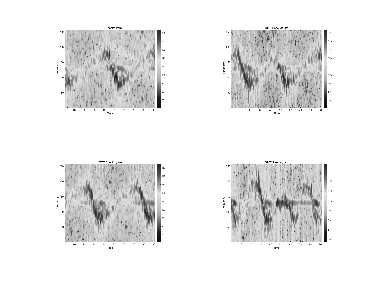

figure;
perm = randperm(70,4);
for i = 1:4
    subplot(2,2,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds)

labelCount = 14×2 table
    Label    Count
    _____    _____

      A       20  
      B       20  
      C       20  
      D       20  
      E       20  
      F       20  
      G       20  
      H       20  
      I       20  
      J       20  
      K       20  
      L       20  
      M       20  
      N       20  


img = readimage(imds,1);
size(img)

ans =          875        1167


numTrainFiles = 15;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

layers = [
    imageInputLayer(size(img))
    
    convolution2dLayer(10,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(10,'Stride',10)
    
    convolution2dLayer(10,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(10,'Stride',10)
    
    convolution2dLayer(10,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(14)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.02, ...
    'MaxEpochs',50, ...
    'MiniBatchSize',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',5, ...
    'Verbose',false, ...
    'CheckpointPath',checkpointPath, ...
    'Plots','training-progress');

% For checkponit only
options_checkpoint = trainingOptions('adam', ...
   'InitialLearnRate',eps, ...
   'ResetInputNormalization',false,...
   'ExecutionEnvironment','auto', ...
   'MiniBatchSize',1, ...
   'OutputFcn',@(~)true );

net = trainNetwork(imdsTrain,layers,options);
% net = trainNetwork(imdsTrain,layerGraph(net),options_checkpoint);

YPred = classify(net,imdsValidation,'ExecutionEnvironment','cpu');
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.1143